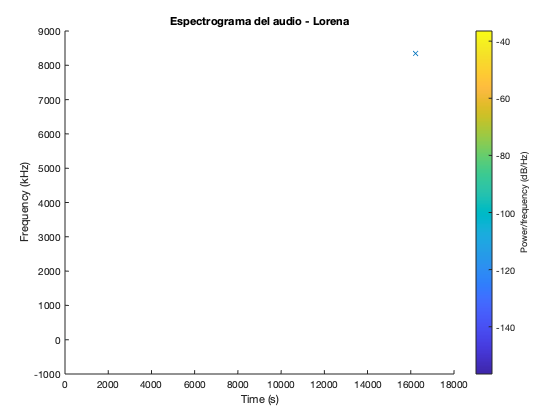

[y, Fs] = audioread('uLore.wav');
info = audioinfo('uLore.wav');
%sound(y, Fs);
duracion = info.Duration;
y = y(:,1);

ventana = 100;
noverlap = 90;
NFFT = 128;
spectrogram(y, ventana, noverlap, NFFT, Fs, 'yaxis');
title('Espectrograma del audio - Lorena')

tiempo = 0

ans = 'halp'

tiempo = 0.0200

ans = 'halp'

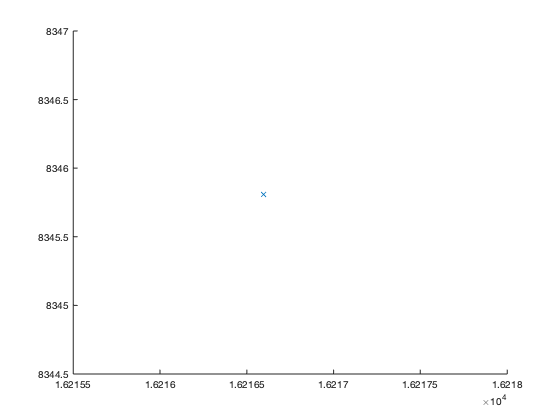

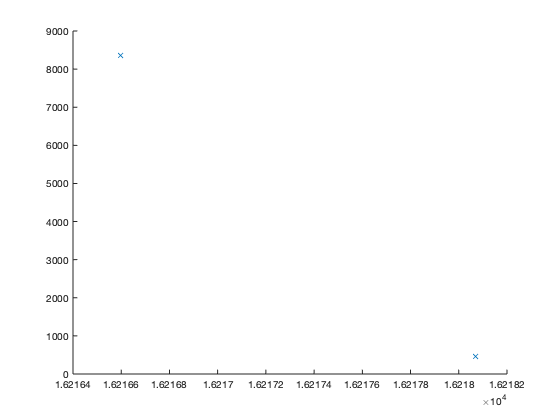

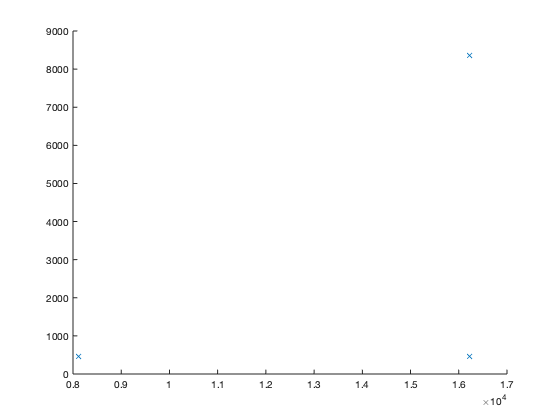

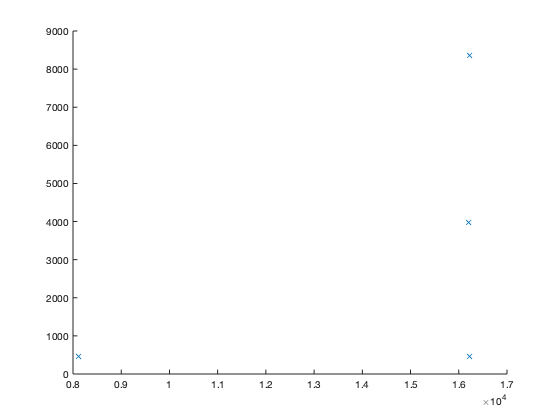

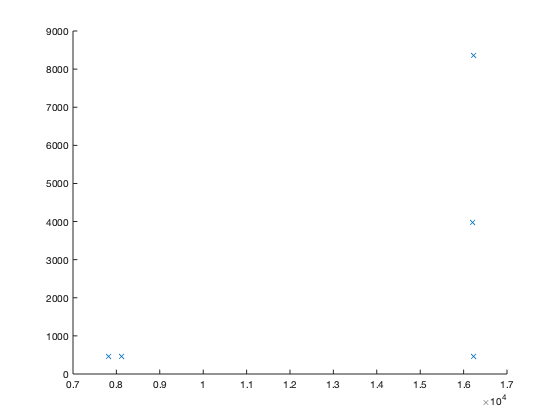

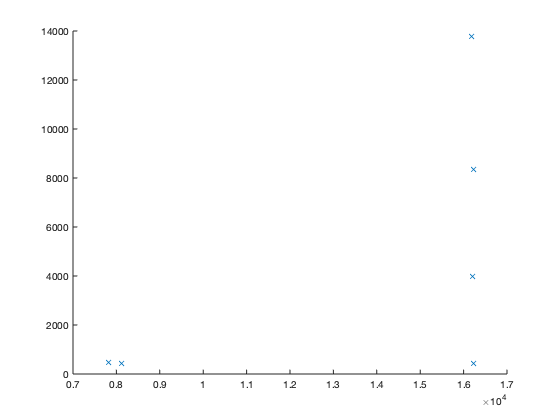

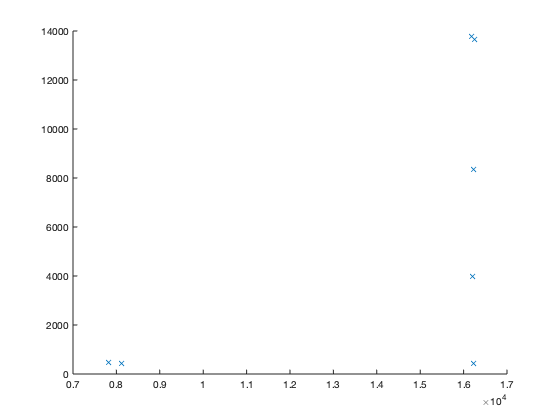

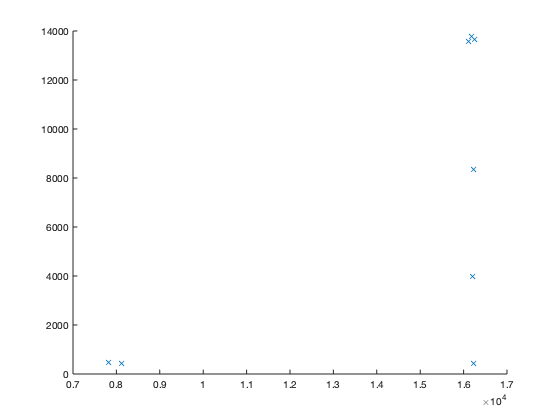

[s, w, t] = spectrogram(y, 'yaxis');

tiempo = 0;
delta = 0.02;
m = 0;

for tiempo = 0:delta:1
    inicio = floor(tiempo / (1 / Fs)) + 1;
    fin = floor((tiempo + delta) / (1 / Fs)) + 1;
    % W = rango de tiempo
    w = y(inicio:fin); 

    try
        [formante] =  obtenerFormantes(w, Fs, ' ');
        m = m + 1;
        tam = min(3, length(formante));
        
        Formantes(m, :) = [NaN, NaN, NaN];
        
       
        Formantes(m, 1:tam) = formante(1:tam);
        
        hold on
        plot(Formantes(:, 1), Formantes(:, 2), 'x')
    catch ME
        tiempo
        sprintf('halp')
    end   
end


prom = nanmean(Formantes)

prom = 	1.0e+04 *

    1.0209    0.9699    0.6690


%plot(Formantes, 'x')

Prueba Hola Mundo

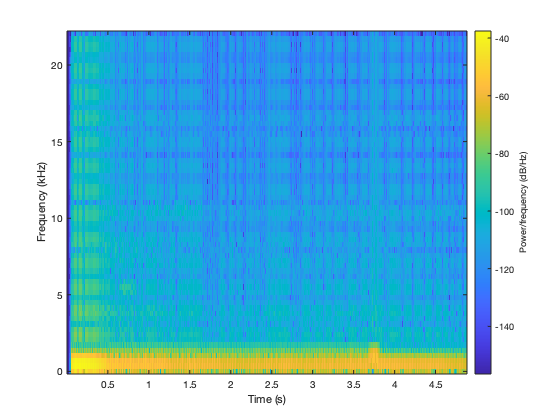

[y, Fs] = audioread('oLore.wav');
info = audioinfo('oLore.wav');
duracion = info.Duration;
y = y(:,1);

ventana = 100;
noverlap = 90;
NFFT = 128;
spectrogram(y, ventana, noverlap, NFFT, Fs, 'yaxis');


load('BaseDeDatos.mat',"data");
vocales = vertcat(data.formantes);

tiempo = 0;
delta = 0.02; 

for tiempo = 0:delta:(duracion - delta)
    inicio = floor(tiempo / (1 / Fs)) + 1;
    fin = floor((tiempo + delta) / (1 / Fs)) + 1;
    % W = rango de tiempo
    w = y(inicio:fin); 

    try
        [formanteAux] =  obtenerFormantes(w, Fs, ' ');
        tam = min(3, length(formante));
        formante = [NaN, NaN, NaN];
        formante (1:tam) = formanteAux(1:tam);
        %formante
        
        idx = knnsearch(vocales, formante);
        objetivo = vocales(idx, :);
        
        for i = 1:length(data) 
            if ismember(data(i).formantes, objetivo, 'rows') == [1, 1, 1]
                letra = data(i).val   
            end
        end
    catch ME
        tiempo
        sprintf('halp')
    end   
end

tiempo = 0

ans = 'halp'

letra = 'i'

tiempo = 0.0400

ans = 'halp'

letra = 'i'

letra = 'u'

letra = 'u'

tiempo = 0.1200

ans = 'halp'

letra = 'u'

letra = 'i'

letra = 'u'

letra = 'u'

tiempo = 0.2200

ans = 'halp'

letra = 'a'

tiempo = 0.2600

ans = 'halp'

tiempo = 0.2800

ans = 'halp'

letra = 'a'

letra = 'u'

letra = 'u'

letra = 'i'

letra = 'i'

letra = 'o'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'i'

letra = 'o'

letra = 'o'

letra = 'e'

letra = 'e'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'i'

letra = 'o'

letra = 'i'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'i'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'o'

letra = 'e'

letra = 'e'

letra = 'i'

letra = 'e'

letra = 'i'

letra = 'i'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'i'

letra = 'i'

letra = 'e'

letra = 'e'

letra = 'i'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'e'

letra = 'i'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'e'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'i'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'e'

letra = 'e'

letra = 'e'

letra = 'i'

letra = 'e'

letra = 'e'

letra = 'u'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'e'

letra = 'e'

letra = 'e'

letra = 'e'

letra = 'e'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'i'

letra = 'i'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'u'

letra = 'e'

letra = 'e'

letra = 'i'

letra = 'i'

letra = 'u'

letra = 'u'

letra = 'o'

letra = 'u'

letra = 'o'

letra = 'u'

% idx = knnsearch(vocales, [1.3012, 1.0140, 0.9013])
% objetivo = vocales(idx, :)
% 
% for i = 1:length(data) 
%     if ismember(data(i).formantes, objetivo, 'rows') == [1, 1, 1]
%         letra = data(i).val   
%     end
% end

function [Formantes] = obtenerFormantes (Audio, FS, Titulo)

Canal1 = Audio(:,1);
n = length(Canal1);
ventana = hamming(n).*Canal1;

grado = 22;
filtro = filter([1 0.63], [1],ventana);
A = lpc(filtro, grado);

[h, w] = freqz([1],A,n);

h = 10*log10(abs(h));
w = (w * (FS/(2*pi)));

raices = roots(A).';
[R,indices,basura] = unique(real(raices));
I= imag(raices);
I = I(indices);

[theta,rho] = cart2pol(R,I);

Theta = (FS/(2*pi)) * theta;
Ancho_Banda = (-1/2)*(FS/(2*pi))*log(rho);
Formantes = 0;

for i = 1:length(Ancho_Banda)
    if(Ancho_Banda(i)<400 & Theta(i)>90)
        if(Formantes(1) == 0)
            Formantes(1) = Theta(i);
        else
            Formantes(end+1)=Theta(i);
        end
    end
end

%Titulo1 = strcat('Audio de:',Titulo);
%figure %Grafica de Freqz
    %freqz([1],A,n)
    %title(Titulo1)

TF = 10*log10(abs(fft(Canal1, FS))); %fft
Titulo2 = strcat('Formantes vs Audio' ,Titulo);
figure %Formantes vs fft
    
%     hold on
%     grid on
%     plot(TF,'color', [1, 0.8, 0])
%     axis([0, FS/2, -inf, inf])
%     plot(w,h,'color', [0.6350, 0.0780, 0.1840], 'linewidth', 3)
%     title(Titulo2)
%     hold off
end